          RIS 4x4 STATE TRANSITION DIAGNOSTIC


Frequency              = 2.450 GHz


Wavelength              = 122.364 mm


Element pitch           = 61.0 mm


Pitch / wavelength      = 0.4985 lambda



HFSS UNIT CELL STATES


ON phase                = +148.9220 deg


OFF phase               = -70.2555 deg


ON magnitude            =   0.8447


OFF magnitude           =   0.8599



Circular phase difference = -140.8225 deg


                  TEST CONFIGURATIONS



ALL OFF


----------------------


     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0




ALL ON


----------------------


     1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1




LEFT ON / RIGHT OFF


----------------------


     1     1     0     0
     1     1     0     0
     1     1     0     0
     1     1     0     0




LEFT OFF / RIGHT ON


----------------------


     0     0     1     1
     0     0     1     1
     0     0     1     1
     0     0     1     1



                 STEERING RESULTS


Configuration                Beam Angle      Peak           


------------------------------------------------------------


ALL OFF                         +0.00 deg         +0.00 dB
ALL ON                          +0.00 deg         +0.00 dB
LEFT ON / RIGHT OFF            -18.05 deg         +0.00 dB
LEFT OFF / RIGHT ON            +18.05 deg         +0.00 dB


             STATE TRANSITION ANALYSIS



ALL OFF beam =    +0.00 deg


ALL ON  beam =    +0.00 deg



LEFT ON / RIGHT OFF beam =   -18.05 deg


LEFT OFF / RIGHT ON beam =   +18.05 deg



Difference between complementary patterns:


Beam separation =   +36.10 deg


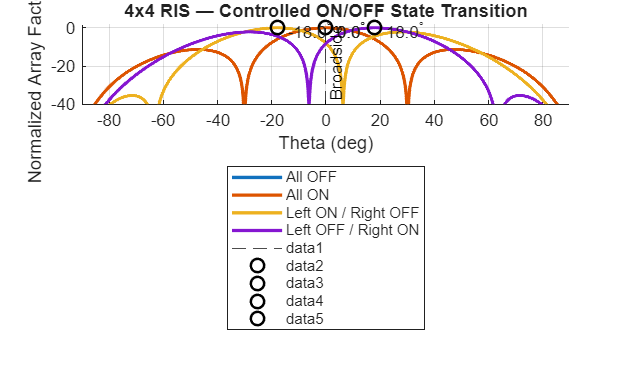

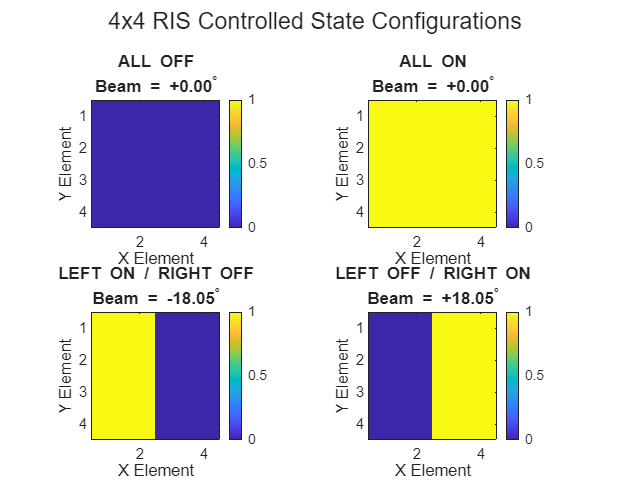

                     DIAGNOSTIC



PASS: Complementary X-direction configurations
produce steering in opposite directions.



Next step:
Use the LEFT ON / RIGHT OFF and LEFT OFF / RIGHT ON
matrices exactly as printed above in HFSS.



Then compare the HFSS beam angles with MATLAB.
Do NOT optimize the array yet.


%% ============================================================
% RIS 4x4 VALIDATION + HIGHER ARRAY SCALING STUDY
%
% PURPOSE
% -------
% 1. Validate the actual 4x4 RIS using HFSS unit-cell data.
% 2. Demonstrate the controlled +/- steering states.
% 3. Explain the limitation of 1-bit 4x4 steering.
% 4. Predict what larger arrays could achieve using the
%    SAME physical HFSS ON/OFF states.
%
% IMPORTANT:
% Higher-array results are MATLAB ARRAY-FACTOR predictions.
% They are NOT HFSS results.
%
% HFSS UNIT CELL DATA
% -------------------
% Frequency       = 2.45 GHz
% ON phase        = +148.922 deg
% OFF phase       = -70.2555 deg
% ON magnitude    = -1.4661 dB
% OFF magnitude   = -1.3114 dB
% Element pitch   = 61 mm
%
% =============================================================

clear;
clc;
close all;

%% ============================================================
% 1. PHYSICAL PARAMETERS
% ============================================================

f = 2.45e9;
c = 299792458;

lambda = c/f;
k = 2*pi/lambda;

pitch = 61e-3;                 % metres
pitch_lambda = pitch/lambda;

% Array sizes for scaling study
arraySizes = [4 8 12 16];

% Steering targets
targetAngles = [0 10 20 30];

% Observation angle
theta = -90:0.05:90;

fprintf('\n');
fprintf('============================================================\n');
fprintf('        RIS 4x4 VALIDATION + ARRAY SCALING STUDY\n');
fprintf('============================================================\n');

fprintf('Frequency              = %.3f GHz\n',f/1e9);
fprintf('Wavelength             = %.4f mm\n',lambda*1000);
fprintf('Element pitch          = %.2f mm\n',pitch*1000);
fprintf('Pitch / lambda         = %.4f lambda\n',pitch_lambda);

%% ============================================================
% 2. ACTUAL HFSS UNIT-CELL DATA
% ============================================================

phaseON  = 148.9220;
phaseOFF = -70.2555;

magON_dB  = -1.4661;
magOFF_dB = -1.3114;

magON  = 10^(magON_dB/20);
magOFF = 10^(magOFF_dB/20);

% Wrapped phase difference
deltaPhase = angle( ...
    exp(1j*deg2rad(phaseON-phaseOFF)));

deltaPhaseDeg = rad2deg(deltaPhase);

fprintf('\n');
fprintf('HFSS UNIT CELL DATA\n');
fprintf('------------------------------------------------------------\n');
fprintf('ON phase               = %+9.4f deg\n',phaseON);
fprintf('OFF phase              = %+9.4f deg\n',phaseOFF);
fprintf('ON magnitude           = %9.4f\n',magON);
fprintf('OFF magnitude          = %9.4f\n',magOFF);
fprintf('Wrapped phase diff.    = %+9.4f deg\n',deltaPhaseDeg);
fprintf('Absolute phase diff.   = %9.4f deg\n',abs(deltaPhaseDeg));

%% ============================================================
% 3. PHASE GRADIENT REQUIRED FOR TARGET ANGLES
% ============================================================

fprintf('\n');
fprintf('============================================================\n');
fprintf('       REQUIRED CONTINUOUS PHASE GRADIENT\n');
fprintf('============================================================\n');

fprintf(' Target      Required phase step / element\n');
fprintf('  (deg)              (deg)\n');
fprintf('------------------------------------------------------------\n');

for target = targetAngles

    requiredStep = -360*(pitch/lambda)*sind(target);

    fprintf(' %5.1f              %+8.3f\n', ...
        target,requiredStep);

end

fprintf('------------------------------------------------------------\n');

fprintf(['\nNOTE:\n' ...
         'The required phase step is continuous, but the physical\n' ...
         'RIS only has two available phase states separated by\n' ...
         '%.3f degrees.\n'],abs(deltaPhaseDeg));

%% ============================================================
% 4. 4x4 ELEMENT COORDINATES
% ============================================================

N = 4;

[x4,y4] = createCoordinates(N,pitch);

%% ============================================================
% 5. CONTROLLED 4x4 CONFIGURATIONS
% ============================================================

configAllOFF = zeros(4,4);

configAllON = ones(4,4);

configLeftON = [ ...
    1 1 0 0;
    1 1 0 0;
    1 1 0 0;
    1 1 0 0];

configRightON = [ ...
    0 0 1 1;
    0 0 1 1;
    0 0 1 1;
    0 0 1 1];

controlledConfigs = {
    configAllOFF
    configAllON
    configLeftON
    configRightON
};

controlledNames = {
    'All OFF'
    'All ON'
    'Left ON / Right OFF'
    'Left OFF / Right ON'
};

%% ============================================================
% 6. CONTROLLED 4x4 TEST
% ============================================================

controlledPatterns = zeros(4,length(theta));
controlledBeams = zeros(4,1);

fprintf('\n');
fprintf('============================================================\n');
fprintf('             CONTROLLED 4x4 VALIDATION\n');
fprintf('============================================================\n');

for q = 1:4

    config = controlledConfigs{q};

    AF = calculateAF2D( ...
        config,x4,y4,k,theta, ...
        phaseON,phaseOFF,magON,magOFF);

    P = abs(AF);
    P = P/max(P);

    PdB = 20*log10(P+1e-12);

    controlledPatterns(q,:) = PdB;

    [~,idx] = max(P);

    controlledBeams(q) = theta(idx);

    fprintf('%-30s : %+8.2f deg\n', ...
        controlledNames{q},controlledBeams(q));

end

%% ============================================================
% 7. PLOT CONTROLLED STATES
% ============================================================

figure( ...
    'Name','4x4 Controlled State Validation', ...
    'Position',[100 100 950 600]);

hold on;
grid on;

for q = 1:4

    plot( ...
        theta, ...
        controlledPatterns(q,:), ...
        'LineWidth',2, ...
        'DisplayName',sprintf( ...
            '%s (%.2f°)', ...
            controlledNames{q}, ...
            controlledBeams(q)));

end

xline(0,'--','Broadside');

xlabel('Theta (deg)');
ylabel('Normalized Array Factor (dB)');

title('4x4 RIS: Controlled ON/OFF State Validation');

xlim([-60 60]);
ylim([-35 2]);

legend('Location','southoutside');

%% ============================================================
% 8. REQUIRED VS ACTUAL 1-BIT QUANTIZATION
% ============================================================

fprintf('\n');
fprintf('============================================================\n');
fprintf('          4x4 PHYSICAL 1-BIT QUANTIZATION\n');
fprintf('============================================================\n');

quantizedResults = [];

for target = targetAngles

    % Required continuous phase
    phaseRequired = ...
        -k*x4*sind(target);

    % Circular distance to each actual state
    distON = abs(angle( ...
        exp(1j*(phaseRequired-deg2rad(phaseON)))));

    distOFF = abs(angle( ...
        exp(1j*(phaseRequired-deg2rad(phaseOFF)))));

    state = double(distON < distOFF);

    % Exact physical configuration
    config = reshape(state,N,N);

    % Predict actual beam
    AF = calculateAF2D( ...
        config,x4,y4,k,theta, ...
        phaseON,phaseOFF,magON,magOFF);

    P = abs(AF);
    P = P/max(P);

    [~,idxGlobal] = max(P);

    actualBeam = theta(idxGlobal);

    error = actualBeam-target;

    % Target level
    [~,idxTarget] = min(abs(theta-target));

    targetLevel = 20*log10(P(idxTarget)+1e-12);

    % Specular level
    [~,idxZero] = min(abs(theta));

    specularLevel = 20*log10(P(idxZero)+1e-12);

    % Target versus specular
    targetVsSpecular = targetLevel-specularLevel;

    quantizedResults = [ ...
        quantizedResults;
        target actualBeam error ...
        targetLevel specularLevel targetVsSpecular];

    fprintf('\nTarget = %+5.1f deg\n',target);
    fprintf('Matrix:\n');
    disp(config);

    fprintf('Actual predicted beam = %+8.2f deg\n',actualBeam);
    fprintf('Steering error        = %+8.2f deg\n',error);
    fprintf('Target level         = %+8.2f dB\n',targetLevel);
    fprintf('Specular level       = %+8.2f dB\n',specularLevel);
    fprintf('Target - specular    = %+8.2f dB\n',targetVsSpecular);

end

%% ============================================================
% 9. TABLE FOR 4x4
% ============================================================

fprintf('\n');
fprintf('============================================================\n');
fprintf('                    4x4 SUMMARY\n');
fprintf('============================================================\n');

fprintf([' Target | Actual | Error | Target | Specular | Target-Spec\n' ...
         '        | Beam   |       | Level  | Level    |              \n']);

fprintf('------------------------------------------------------------\n');

for r = 1:size(quantizedResults,1)

    fprintf( ...
        '%6.1f | %6.2f | %+5.2f | %6.2f | %8.2f | %+9.2f\n', ...
        quantizedResults(r,1), ...
        quantizedResults(r,2), ...
        quantizedResults(r,3), ...
        quantizedResults(r,4), ...
        quantizedResults(r,5), ...
        quantizedResults(r,6));

end

%% ============================================================
% 10. PLOT 4x4 QUANTIZED STEERING
% ============================================================

figure( ...
    'Name','4x4 Quantized Steering', ...
    'Position',[150 150 950 600]);

hold on;
grid on;

for target = targetAngles

    phaseRequired = ...
        -k*x4*sind(target);

    distON = abs(angle( ...
        exp(1j*(phaseRequired-deg2rad(phaseON)))));

    distOFF = abs(angle( ...
        exp(1j*(phaseRequired-deg2rad(phaseOFF)))));

    state = double(distON < distOFF);

    config = reshape(state,N,N);

    AF = calculateAF2D( ...
        config,x4,y4,k,theta, ...
        phaseON,phaseOFF,magON,magOFF);

    P = abs(AF);
    P = P/max(P);

    PdB = 20*log10(P+1e-12);

    plot( ...
        theta,PdB, ...
        'LineWidth',1.8, ...
        'DisplayName',sprintf( ...
            'Target %d°',target));

end

xline(0,'--','Broadside');

xlabel('Theta (deg)');
ylabel('Normalized Array Factor (dB)');

title('4x4: Physically Quantized 1-Bit Steering');

xlim([-60 60]);
ylim([-35 2]);

legend('Location','southoutside');

%% ============================================================
% 11. HIGHER ARRAY STUDY
% ============================================================

fprintf('\n');
fprintf('============================================================\n');
fprintf('            HIGHER ARRAY SCALING STUDY\n');
fprintf('============================================================\n');

fprintf(['\nIMPORTANT:\n' ...
         'These are ARRAY-FACTOR predictions using the same HFSS\n' ...
         'unit-cell ON/OFF data. They are NOT HFSS results.\n']);

%% Optimization settings

% Number of optimization iterations
numIterations = 3000;

% Number of random restarts
numRestarts = 3;

% Target weighting
targetWeight = 1.0;

% Specular suppression weighting
specularWeight = 1.0;

% Global unwanted-beam penalty
globalWeight = 0.4;

higherResults = [];

%% ============================================================
% 12. HIGHER ARRAY OPTIMIZATION
% ============================================================

for N = arraySizes

    [xN,yN] = createCoordinates(N,pitch);

    physicalSize = (N-1)*pitch*1000;

    fprintf('\n');
    fprintf('------------------------------------------------------------\n');
    fprintf('ARRAY %dx%d\n',N,N);
    fprintf('Elements          = %d\n',N^2);
    fprintf('Physical aperture = %.1f mm x %.1f mm\n', ...
        physicalSize,physicalSize);

    for target = targetAngles

        fprintf('Target = %+5.1f deg ... ',target);

        [bestConfig,bestMetrics] = optimizeBinaryArray( ...
            N,xN,yN,k,theta, ...
            phaseON,phaseOFF, ...
            magON,magOFF, ...
            target, ...
            numIterations, ...
            numRestarts, ...
            targetWeight, ...
            specularWeight, ...
            globalWeight);

        higherResults = [ ...
            higherResults;
            N target ...
            physicalSize ...
            bestMetrics.beam ...
            bestMetrics.error ...
            bestMetrics.targetLevel ...
            bestMetrics.specularLevel ...
            bestMetrics.targetVsSpecular ...
            bestMetrics.HPBW ...
            bestMetrics.SLL];

        fprintf('beam = %+7.2f deg, error = %+7.2f deg\n', ...
            bestMetrics.beam, ...
            bestMetrics.error);

    end

end

%% ============================================================
% 13. PRINT HIGHER ARRAY TABLE
% ============================================================

fprintf('\n');
fprintf('============================================================\n');
fprintf('             HIGHER ARRAY PREDICTION TABLE\n');
fprintf('============================================================\n');

fprintf(['Array | Size | Target | Beam | Error | Target | Specular |\n' ...
         '      | mm   |        |      |       | dB     | dB       |\n']);

fprintf('------------------------------------------------------------\n');

for r = 1:size(higherResults,1)

    fprintf( ...
        '%2dx%-2d | %4.0f | %6.1f | %5.1f | %+5.1f | %6.2f | %8.2f\n', ...
        higherResults(r,1), ...
        higherResults(r,1), ...
        higherResults(r,3), ...
        higherResults(r,2), ...
        higherResults(r,4), ...
        higherResults(r,5), ...
        higherResults(r,6), ...
        higherResults(r,7));

end

fprintf('============================================================\n');

%% ============================================================
% 14. REALISTIC HIGHER-ARRAY PLOT
% ============================================================

% Choose 8x8 and 20 degree as illustrative higher-array case

Nplot = 8;
targetPlot = 20;

[xPlot,yPlot] = createCoordinates(Nplot,pitch);

fprintf('\n');
fprintf('============================================================\n');
fprintf('             8x8 ILLUSTRATIVE CASE\n');
fprintf('============================================================\n');

[config8,best8] = optimizeBinaryArray( ...
    Nplot,xPlot,yPlot,k,theta, ...
    phaseON,phaseOFF, ...
    magON,magOFF, ...
    targetPlot, ...
    numIterations, ...
    numRestarts, ...
    targetWeight, ...
    specularWeight, ...
    globalWeight);

fprintf('8x8 target             = %+7.2f deg\n',targetPlot);
fprintf('8x8 predicted beam     = %+7.2f deg\n',best8.beam);
fprintf('8x8 steering error     = %+7.2f deg\n',best8.error);
fprintf('8x8 physical aperture  = %.1f x %.1f mm\n', ...
    (Nplot-1)*pitch*1000, ...
    (Nplot-1)*pitch*1000);

fprintf('\n8x8 optimized binary matrix:\n');
disp(config8);

%% Calculate final 8x8 pattern

AF8 = calculateAF2D( ...
    config8,xPlot,yPlot,k,theta, ...
    phaseON,phaseOFF,magON,magOFF);

P8 = abs(AF8);
P8 = P8/max(P8);

P8dB = 20*log10(P8+1e-12);

figure( ...
    'Name','4x4 versus 8x8 Prediction', ...
    'Position',[200 200 950 600]);

hold on;
grid on;

% 4x4 controlled positive steering
AF4 = calculateAF2D( ...
    configRightON,x4,y4,k,theta, ...
    phaseON,phaseOFF,magON,magOFF);

P4 = abs(AF4);
P4 = P4/max(P4);

P4dB = 20*log10(P4+1e-12);

plot(theta,P4dB, ...
    'LineWidth',2, ...
    'DisplayName', ...
    sprintf('4x4 measured-state model (beam %.1f°)', ...
    controlledBeams(4)));

plot(theta,P8dB, ...
    'LineWidth',2, ...
    'DisplayName', ...
    sprintf('8x8 predicted optimized (target %.0f°, beam %.1f°)', ...
    targetPlot,best8.beam));

xline(0,'--','Broadside');
xline(targetPlot,':','20° target');

xlabel('Theta (deg)');
ylabel('Normalized Array Factor (dB)');

title('4x4 vs Higher-Array Beam-Steering Prediction');

xlim([-60 60]);
ylim([-35 2]);

legend('Location','southoutside');

%% ============================================================
% 15. PHYSICAL SIZE TABLE
% ============================================================

fprintf('\n');
fprintf('============================================================\n');
fprintf('                 PHYSICAL ARRAY SIZES\n');
fprintf('============================================================\n');

fprintf('Array      Elements       Aperture\n');
fprintf('--------------------------------------------\n');

for N = arraySizes

    sizeMM = (N-1)*pitch*1000;

    fprintf('%2dx%-2d        %3d          %7.1f x %7.1f mm\n', ...
        N,N,N^2,sizeMM,sizeMM);

end

%% ============================================================
% 16. FINAL INTERPRETATION
% ============================================================

fprintf('\n');
fprintf('============================================================\n');
fprintf('                    INTERPRETATION\n');
fprintf('============================================================\n');

fprintf([ ...
'\nYour 4x4 array is NOT incapable of beam steering.\n' ...
'\n' ...
'The controlled-state test demonstrated that the two\n' ...
'complementary phase distributions produce approximately\n' ...
'opposite beams.\n' ...
'\n' ...
'The limitation is that 4x4 + 1-bit phase control provides\n' ...
'a very coarse spatial phase approximation. Therefore,\n' ...
'arbitrary targets such as 10, 20 and 30 degrees cannot\n' ...
'necessarily be achieved accurately.\n' ...
'\n' ...
'A larger array provides more spatial samples and more\n' ...
'binary degrees of freedom with which to approximate the\n' ...
'required phase gradient.\n' ...
'\n' ...
'The higher-array results produced here are theoretical\n' ...
'array-factor predictions and must be verified in HFSS\n' ...
'before being presented as electromagnetic simulation results.\n']);

fprintf('============================================================\n');

%% ============================================================
% HELPER FUNCTION 1
% CREATE ARRAY COORDINATES
% ============================================================

function [x,y] = createCoordinates(N,d)

    [xGrid,yGrid] = meshgrid( ...
        ((0:N-1)-(N-1)/2)*d, ...
        ((0:N-1)-(N-1)/2)*d);

    x = xGrid(:);
    y = yGrid(:);

end

%% ============================================================
% HELPER FUNCTION 2
% ARRAY FACTOR
% ============================================================

function AF = calculateAF2D( ...
    config,x,y,k,theta, ...
    phaseON,phaseOFF,magON,magOFF)

    state = config(:);

    phase = zeros(size(state));
    magnitude = zeros(size(state));

    phase(state == 1) = deg2rad(phaseON);
    phase(state == 0) = deg2rad(phaseOFF);

    magnitude(state == 1) = magON;
    magnitude(state == 0) = magOFF;

    AF = zeros(size(theta));

    for n = 1:length(theta)

        th = deg2rad(theta(n));

        % Phi = 0 degree
        steeringPhase = ...
            k*x*sin(th);

        AF(n) = sum( ...
            magnitude .* ...
            exp(1j*(phase+steeringPhase)));

    end

end

%% ============================================================
% HELPER FUNCTION 3
% BINARY ARRAY OPTIMIZATION
% ============================================================

function [bestConfig,bestMetrics] = optimizeBinaryArray( ...
    N,x,y,k,theta, ...
    phaseON,phaseOFF,magON,magOFF, ...
    target, ...
    numIterations, ...
    numRestarts, ...
    targetWeight, ...
    specularWeight, ...
    globalWeight)

    numElements = N*N;

    bestScoreOverall = -Inf;

    %% Target index

    [~,idxTarget] = min(abs(theta-target));

    [~,idxSpecular] = min(abs(theta));

    %% Random restarts

    for restart = 1:numRestarts

        % Random initial state
        state = randi([0 1],numElements,1);

        AF = calculateAF2D( ...
            reshape(state,N,N), ...
            x,y,k,theta, ...
            phaseON,phaseOFF, ...
            magON,magOFF);

        P = abs(AF);
        P = P/max(P);

        currentScore = calculateObjective( ...
            P,idxTarget,idxSpecular, ...
            targetWeight, ...
            specularWeight, ...
            globalWeight);

        %% ----------------------------------------------------
        % Local binary search
        % -----------------------------------------------------

        for iter = 1:numIterations

            % Randomly flip one element
            idxFlip = randi(numElements);

            candidate = state;

            candidate(idxFlip) = ...
                1-candidate(idxFlip);

            AFcandidate = calculateAF2D( ...
                reshape(candidate,N,N), ...
                x,y,k,theta, ...
                phaseON,phaseOFF, ...
                magON,magOFF);

            Pcandidate = abs(AFcandidate);

            Pcandidate = ...
                Pcandidate/max(Pcandidate);

            candidateScore = calculateObjective( ...
                Pcandidate, ...
                idxTarget, ...
                idxSpecular, ...
                targetWeight, ...
                specularWeight, ...
                globalWeight);

            % Accept improvement
            if candidateScore > currentScore

                state = candidate;
                currentScore = candidateScore;
                P = Pcandidate;

            end

        end

        %% Keep best restart

        if currentScore > bestScoreOverall

            bestScoreOverall = currentScore;
            bestState = state;
            bestP = P;

        end

    end

    %% --------------------------------------------------------
    % Final metrics
    % ---------------------------------------------------------

    bestConfig = reshape(bestState,N,N);

    [peakValue,idxGlobal] = max(bestP);

    beam = theta(idxGlobal);

    error = beam-target;

    targetLevel = ...
        20*log10(bestP(idxTarget)+1e-12);

    specularLevel = ...
        20*log10(bestP(idxSpecular)+1e-12);

    targetVsSpecular = ...
        targetLevel-specularLevel;

    % HPBW
    HPBW = calculateHPBW( ...
        theta, ...
        20*log10(bestP+1e-12), ...
        idxGlobal);

    % SLL
    SLL = calculateSLL( ...
        theta, ...
        20*log10(bestP+1e-12), ...
        idxGlobal, ...
        HPBW);

    bestMetrics.beam = beam;
    bestMetrics.error = error;
    bestMetrics.targetLevel = targetLevel;
    bestMetrics.specularLevel = specularLevel;
    bestMetrics.targetVsSpecular = targetVsSpecular;
    bestMetrics.HPBW = HPBW;
    bestMetrics.SLL = SLL;

end

%% ============================================================
% HELPER FUNCTION 4
% OPTIMIZATION OBJECTIVE
% ============================================================

function score = calculateObjective( ...
    P,idxTarget,idxSpecular, ...
    targetWeight, ...
    specularWeight, ...
    globalWeight)

    % Target power
    targetPower = P(idxTarget)^2;

    % Specular power
    specularPower = P(idxSpecular)^2;

    % Global maximum
    globalPower = max(P)^2;

    % Penalize specular dominance
    specularPenalty = specularPower;

    % Penalize excessive global dominance away from target
    globalPenalty = globalPower-targetPower;

    score = ...
        targetWeight*targetPower ...
        - specularWeight*specularPenalty ...
        - globalWeight*max(globalPenalty,0);

end

%% ============================================================
% HELPER FUNCTION 5
% HPBW
% ============================================================

function HPBW = calculateHPBW(theta,PdB,idxPeak)

    level = -3;

    left = idxPeak;
    right = idxPeak;

    while left > 1 && PdB(left) >= level
        left = left-1;
    end

    while right < length(PdB) && PdB(right) >= level
        right = right+1;
    end

    if left == 1 || right == length(PdB)

        HPBW = NaN;

    else

        HPBW = theta(right)-theta(left);

    end

end

%% ============================================================
% HELPER FUNCTION 6
% SLL
% ============================================================

function SLL = calculateSLL(theta,PdB,idxPeak,HPBW)

    if isnan(HPBW)

        SLL = NaN;
        return;

    end

    peakAngle = theta(idxPeak);

    exclusion = ...
        abs(theta-peakAngle) <= HPBW/2;

    sidelobes = PdB(~exclusion);

    if isempty(sidelobes)

        SLL = NaN;

    else

        SLL = max(sidelobes);

    end

end